## Data Preprocessing and Custom Training Function

### Εισαγωγή δεδομένων και μια προεπεξεργασία

Σε αυτό το Notebook θα δούμε πως επεξεργαζόμαστε τα δεδομένα και πως μπορούμε να δημιουργήσουμε την δική μας επαναληπτική διαδικασία/training loop αντί να χρησιμοποιούμε την έτοιμη συνάρτηση **train Network **με στόχο την μεγαλύτερη ευελιξία.

Αρχικά,θα δούμε λίγο πως να επεξεργαζόμαστε τα δεδομένα μας, εφαρμόζοντας **φίλτρα**,**στατιστικούς** **ελέγχους** αλλά και διάφορους **μετασχηματισμούς/feature engineering.**

Χρησιμοποιούμε την συνάρτηση get_housing_data όπως και στο τελευταίο Notebook ώστε να εισαγάγουμε τα δεδομένα μας στο workspace.

clear all
close all
data = get_housing_data();


data.encoded_values = zeros(size(data,1),1);

Για να έχουμε μία γρήγορη περιγραφή των δεδομένων μας μπορούμε να χρησιμοποιήσουμε τη έτοιμη συνάρτηση summary που κάνει ακριβώς αυτό που σημαίνει, περιγράφει συνοπτικά τα δεδομένα μας, αν είναι αριθμητικά τότε μας δίνει min, median και max και αν είναι κατηγορικά τότε μας δίνει την συχνότητα κάθε παρατήρησης.

summary(data)

Variables:

    longitude: 20640×1 double

        Values:

            Min       -124.35 
            Median    -118.49 
            Max       -114.31 

    latitude: 20640×1 double

        Values:

            Min        32.54  
            Median     34.26  
            Max        41.95  

    housing_median_age: 20640×1 double

        Values:

            Min           1   
            Median       29   
            Max          52   

    total_rooms: 20640×1 double

        Values:

            Min            2  
            Median      2127  
            Max        39320  

    total_bedrooms: 20640×1 double

        Values:

            Min             1     
            Median          435   
            Max             6445  
            NumMissing      207   

    population: 20640×1 double

        Values:

            Min            3  
            Median      1166  
   

C = unique(data(:,size(data,2)-1));
unique_values = size(C,1);
encoded_data = onehotencode(data(:,'ocean_proximity'));
for jj =1:unique_values
    data(encoded_data{:,jj}==1,'encoded_values') = array2table(ones(sum(encoded_data{:,jj}==1),1)*jj);
end

Αφαιρούμε την στήλη **'ocean_proximity'** αφού πλέον την έχουμε κωδικοποιήσει σε αριθμούς μεταξύ του 1-5.

data = removevars(data,{'ocean_proximity'});

stats = grpstats(data,'encoded_values', {'mean'})

stats = 5×11 table
         encoded_values    GroupCount    mean_longitude    mean_latitude    mean_housing_median_age    mean_total_rooms    mean_total_bedrooms    mean_population    mean_households    mean_median_income    mean_median_house_value
         ______________    __________    ______________    _____________    _______________________    ________________    ___________________    _______________    _______________    __________________    _______________________

    1          1              9136          -118.85           34.561                29.279                  2628.3               

Χρησιμοποιούμε τις εντολές head και tail για να δούμε γρήγορα τις πρώτες k γραμμές καθώς και τις τελευταίες k γραμμές του table.

k=5;
head(data,k)

    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    median_house_value    encoded_values
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    __________________    ______________

     -122.23      37.88              41                880              129             322           126          8.3252            4.526e+05               4       
     -122.22      37.86              21               7099             1106            2401          1138          8.3014            3.585e+05               4   

tail(data,k)

    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    median_house_value    encoded_values
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    __________________    ______________

     -121.09      39.48              25               1665             374              845          330           1.5603              78100                 2       
     -121.21      39.49              18                697             150              356          114           2.5568              77100                 2   

Στη συνέχεια ελέγχουμε για Nan values δηλαδή για εγγραφές που είναι κενές ή έχουν την τιμή Nan χρησιμοποιώντας τη συνάρτηση **isnan** που μας γυρνά ένα ένα λογικό πίνακα με τιμές **1** όπου έχουμε τιμή **Nan** και τιμές **0** όπου έχουμε κανονικές τιμές. Παρατηρούμε πως αν χρησιμοποιήσουμε την συνάρτηση **sum** κατά στήλη τότε μπορούμε να δούμε τον συνολικό αριθμό Nan values ανά στήλη. Προφανώς έχουμε μερικές **Nan** τιμές στην **5η** στήλη που είναι η μεταβλητή **total_bedrooms**. 

indexes = isnan(data{:,:});
sum(isnan(data{:,:}))

Ένας άλλος τρόπος να ελέγχεξουμε αν δεν υπάρχουν εγγραφές είναι να χρησιμοποιήσουμε την εντολή **ismissing**

sum(ismissing(data{:,:}))

Ελέγχουμε αν όντως είναι Nan.

data(indexes(:,5),:)

ans = 207×10 table
    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    median_house_value    encoded_values
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    __________________    ______________

     -122.16      37.77              47               1256             NaN              570           218           4.375            1.619e+05               4       
     -122.17      37.75              38                992             NaN              732           259          1.6196                85100

Υπάρχουν διάφοροι τρόποι να αντιμετωπίσει κανείς τις Nan τιμές και γενικά τις μη ομαλές τιμές όπως Null, ' ' αλλά και πιθανά outliers όπως θα δούμε παρακάτω. Η πιο απλή λύση είναι απλώς να παραλείψουμε αυτά τα ελαττωματικά δεδομένα χρησιμοποιώντας την εντολή `rmmissing.`

data = rmmissing(data)

data = 20433×10 table
    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    median_house_value    encoded_values
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    __________________    ______________

     -122.23      37.88              41                880              129             322           126          8.3252            4.526e+05               4       
     -122.22      37.86              21               7099             1106            2401          1138          8.3014            3.585e

Παρατηρούμε πως το νέο table έχει 207 λιγότερες γραμμές άρα όντως όλες οι missing/Nan τιμές έχουν αφαιρεθεί. Αντί για παράλειψη θα μπορούσαμε να αντικαταστήσουμε τις τιμές με είτε τη μέση τιμή ενός παραθύρου γύρω από την τιμή(moving average) είτε με την μέση τιμή όλου του δείγαμτός.

[R, pvalues] = corrplot(data(:,:))

Αν θέλουμε να δούμε απλώς τους συντελεστές μπορούμε να χρησιμοποιήσουμε την εντολή corrcoef και να αλλάξουμε το αποτέλεσμα σε table ώστε να προσθέσουμε τα ονόματα των στηλών για ευκολότερη ερμηνεία.

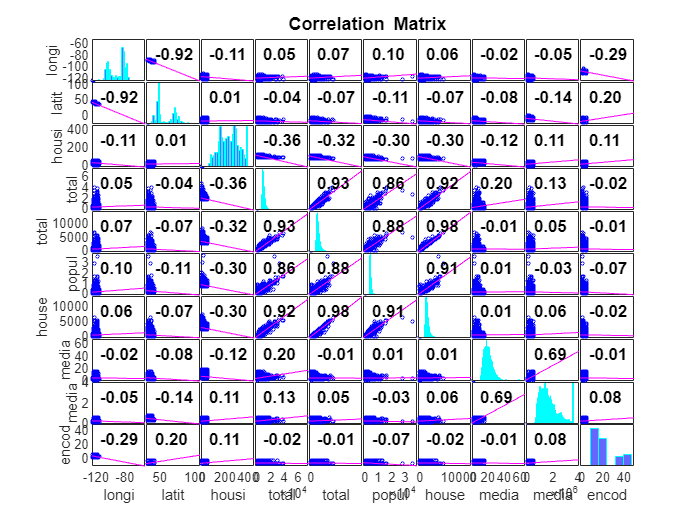

R =     1.0000   -0.9246   -0.1094    0.0455    0.0696    0.1003    0.0565   -0.0156   -0.0454   -0.2895
   -0.9246    1.0000    0.0119   -0.0367   -0.0670   -0.1090   -0.0718   -0.0796   -0.1446    0.2008
   -0.1094    0.0119    1.0000   -0.3606   -0.3205   -0.2958   -0.3028   -0.1183    0.1064    0.1123
    0.0455   -0.0367   -0.3606    1.0000    0.9304    0.8573    0.9190    0.1979    0.1333   -0.0154
    0.0696   -0.0670   -0.3205    0.9304    1.0000    0.8777    0.9797   -0.0077    0.0497   -0.0148
    0.1003   -0.1090   -0.2958    0.8573    0.8777    1.0000    0.9072    0.0051   -0.0253   -0.0696
    0.0565   -0.0718   -0.3028    0.9190    0.9797    0.9072    1.0000    0.0134    0.0649   -0.0183
   -0.0156   -0.0796   -0.1183    0.1979   -0.0077    0.0051    0.0134    1.0000    0.6884   -0.0147
   -0.0454   -0.1446    0.1064    0.1333    0.0497   -0.0253    0.0649    0.6884    1.0000    0.0805
   -0.2895    0.2008    0.1123   -0.0154   -0.0148   -0.0696   -0.0183   -0.0147    0.0

pvalues =     1.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0262    0.0000         0
         0    1.0000    0.0890    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0890    1.0000         0         0         0         0    0.0000    0.0000    0.0000
    0.0000    0.0000         0    1.0000         0         0         0    0.0000    0.0000    0.0281
    0.0000    0.0000         0         0    1.0000         0         0    0.2696    0.0000    0.0348
    0.0000    0.0000         0         0         0    1.0000         0    0.4672    0.0003    0.0000
    0.0000    0.0000         0         0         0         0    1.0000    0.0548    0.0000    0.0091
    0.0262    0.0000    0.0000    0.0000    0.2696    0.4672    0.0548    1.0000         0    0.0359
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000         0    1.0000    0.0000
         0    0.0000    0.0000    0.0281    0.0348    0.0000    0.0091    0.0359 

% Metaferoume thn sthlh median_house_value sthn arxh gia kaluterh
% optikopoihsh

data = movevars(data, 'median_house_value','Before',1);
corr_coeffs = array2table(corrcoef(data{:,:}));
corr_coeffs.Properties.VariableNames = ["median_house_value","longitude", "latitude", "housing_median_age",...
    "total_rooms", "total_bedrooms", "population", "households", "median_income",  "ocean_proximity"];
corr_coeffs{:,:} = round(abs(corr_coeffs{:,:}),2);
corr_coeffs

### Δημιουργία νέων μεταβλητών

Παρατηρούμε πως η μεταβλητή meadian_house_value έχει συσχέτιση μόνο με την μεταβλητή median_income, λογικό καθώς όσο μεγαλύτερο εισόδημα τόσο πιο ακριβό σπίτι μπορεί να αγοράσει κάποιος. Θα θέλαμε να δημιουργήσουμε και άλλες μεταβλητές που να έχουν μεγάλη συσχέτιση με την meadian_house_value, που από δω και στο εξής θα αναφερόμαστε ως y ή target. 

new_feature = data{:,'total_bedrooms'}./ data{:,'total_rooms'};
data.new_feature = new_feature;
new_feature_2 = (data{:,'population'} .* data{:,'households'});
data.new_feature_2 = new_feature_2;

corr_coeffs = 10×10 table
    median_house_value    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    ocean_proximity
    __________________    _________    ________    __________________    ___________    ______________    __________    __________    _____________    _______________

              1             0.05         0.14             0.11              0.13             0.05            0.03          0.06           0.69              0.08      
           0.05                1         0.92             0.11              0.05             0.07             0.1          0.06     

new_feature_3 = (data{:,'total_bedrooms'} ./ data{:,'total_rooms'});
data.new_feature_3 = new_feature_3;

Παρατηρούμε πως οι τρείς νέες μεταβλητές έχουμε μεγαλύτερη συσχέτιση από όλες τις προηγούμενες(εκτός της median_income)

corr_coeffs = array2table(corrcoef(data{:,:}));
corr_coeffs.Properties.VariableNames = ["median_house_value","longitude", "latitude", "housing_median_age",...
    "total_rooms", "total_bedrooms", "population", "households", "median_income",  "ocean_proximity", "new_feature", "new_feature_2", "new_feature_3"];
corr_coeffs{:,:} = round(abs(corr_coeffs{:,:}),2);
corr_coeffs

Μπορούμε να δημιουργήσουμε και άλλες νέες μεταβλητές, με γραμμικούς και όχι συνδιασμούς άλλων παραμέτρων ή και με τον εαυτό τους.

Πριν ποχωρήσουμε στην δημιουργία του νευρωνικού μας πρέπει να κάνουμε ένα τελευταίο βήμα και αυτό είναι η κανονικοποίηση των δεδομένων μας, καθώς βρίσκονται σε διαφορετικές κλίμακες και αυτό μπορεί να δημιουργήσει προβλήματα κατά τη διαδικασία της εκπαίδευσης, όπως οι παράγωγοι να πάρουν μεγάλες τιμές(exploding grediensts), αλλά και να γίνει δύσκολη η διαδικασία μάθησης καθώς στο τελευταίο στρώμα τα αποτελέσματα θα πρέπει να έχουν μεγάλα βάρη ώστε από το {-1,1} λόγω της tanh να φτάσουν κοντα στις εκατοντάδες χιλιάδες. Επίσης, για να περάσουμε τα δεδομένα μας ως mini batches στο minibatchqueue object πρέπει να τα μεταφέρουμε σε δομή datastore ώστε το minibatchqueue να τα φέρει σε μορφή dlarray.

input_columns = (2:13);%[9, 11,13]; % orizoume poies sthles tha xrhsimopoih8oun ws inputs
indexes = randperm(size(data,1)); 
% Xrhsimopoioume to 90% gia training
i_train = floor(size(data,1)/10*9);
i_val = floor(i_train/10) * 9;
num_val_samples = i_train-i_val;
train_data = data(indexes(1:i_train),:);
test_data = data(indexes(i_train:end),:);

corr_coeffs = 13×13 table
    median_house_value    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    ocean_proximity    new_feature    new_feature_2    new_feature_3
    __________________    _________    ________    __________________    ___________    ______________    __________    __________    _____________    _______________    ___________    _____________    _____________

              1             0.05         0.14             0.11              0.13             0.05  

 % enwnnoume ta dedomena se morfh (input,targets)
[normalized_data,C,S] = normalize(train_data, "range");
% normalized_data = (data-C)/S 
normalized_data{1,1} *S{1,1}+ C{1,1} == data{indexes(1),1}

x_train_ds = arrayDatastore(normalized_data{1:i_val,input_columns}); 
y_train_ds = arrayDatastore(normalized_data{1:i_val,1});
train_ds = combine(x_train_ds,y_train_ds);

x_val_ds = arrayDatastore(normalized_data{i_val:end,input_columns}); 
y_val_ds = arrayDatastore(normalized_data{i_val:end,1});
val_ds = combine(x_val_ds,y_val_ds);


### Δημιουργία Δικτύου

Όπώς και στο προηγούμενο μάθημα δημιουργούμε ένα δικό μας νευρωνικό δίκτυο ορίζοντας τα στρώματα(layers)

n_features = size(input_columns,2); % Dialegoume tis tesseris metablhtes me ta kalutera correlations

ans = logical
   0


housing_layers = [
    featureInputLayer(n_features, 'Name','Input_Layer')
    fullyConnectedLayer(512,'Name','Hidden_Layer_1')
    reluLayer('Name','relu_1')
    fullyConnectedLayer(256,'Name','Hidden_Layer_2')
    reluLayer('Name','relu_2')
    fullyConnectedLayer(128,'Name','Hidden_Layer_3')
    reluLayer('Name','relu_3')
    fullyConnectedLayer(1,'Name','Output_Layer')];

    % regressionLayer Paraleipoume to regressionLayer kathws tha
    % dhmiourghsoume to diko mas training loop

net = dlnetwork(housing_layers);

### Δημιουργία custom training loop

Περνάμε τα δεδομένα στο minibatchqueue αντικείμενο και του ορίζουμε το μέγεθος του minibatch

numEpochs = 100;
miniBatchSize = 400;
learnRate = 0.05;
decay = 0.0005;
momentum = 0.9;
numObservationsTrain = train_ds.numpartitions;
numIterationsPerEpoch = ceil(numObservationsTrain / miniBatchSize);
numIterations = numEpochs * numIterationsPerEpoch;
averageGrad = [];
averageSqGrad = [];
epoch = 0;
iteration = 0;
validation_freq = 25;
validation_patience = 10;
validation_results = zeros(ceil(numIterations/validation_freq),1);
mbq = minibatchqueue(train_ds,...
    'OutputCast', {'double'  'double'},...
    'MiniBatchSize',miniBatchSize,...
    'MiniBatchFormat',"BC");
val_mbq = minibatchqueue(val_ds,...
    'OutputCast', {'double'  'double'},...
    'MiniBatchSize',num_val_samples,...
    'MiniBatchFormat',"BC");

Με την εντολή next(mbq) ζητάμε από το αντικείμενο mbq να μας δώσει το επόμενο στη σειρά minibatch και ελέγχουμε πως όλα λειτουργούν σωστά.

Για να ξαναγεμίσουμε τη σειρά απλώς καλούμε την συνάρτηση reset(mqb)

% [x, t] = next(mbq); % Blepoume pws to apotelesma einai 128x4 pinakas gia to X(input data) kai 128x1 gia to t(Target_data)
% % se morfh gpuArray(an exoume CUDA enabled gpu) eidallws aplws dlarray
% forward(net,x);


% An exete egkatesthmeno Matlab 2022b tote mporeite na kalesete to parakatw
% keli kathws kai na kanete uncomment tis grammes sto training loop
monitor = trainingProgressMonitor(Metrics=["TrainingLoss","ValidationLoss"], Info=["Epoch", "LearningRate", "Iteration","RMSE","RMSE_Val"],XLabel="Iteration"); %,"TrainingRMSE", "ValidationRMSE"
%groupSubPlot(monitor,"MSELoss",["TrainingLoss","ValidationLoss"]);
% groupSubPlot(monitor,"MSELoss",["TrainingRMSE", "ValidationRMSE"]);

% Loop over epochs.
while epoch < numEpochs && ~monitor.Stop
    
    epoch = epoch + 1;

    % Shuffle data.
    shuffle(mbq);
    
    % Loop over mini-batches.
    while hasdata(mbq) && ~monitor.Stop


        iteration = iteration + 1;

        % Read mini-batch of data.
        [x_train,y_train] = next(mbq);

        
        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelLoss function and update the network state.
        
        [loss,gradients,state] = dlfeval(@modelLoss,net,x_train,y_train);

        
        net.State = state;
        
        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = learnRate/(1 + decay);
        
        % Update the network parameters using the SGDM optimizer.
         [net,averageGrad,averageSqGrad] = adamupdate(net,gradients,averageGrad,averageSqGrad,iteration,learnRate);
        
        % Update the training progress monitor.
        recordMetrics(monitor,iteration,TrainingLoss=loss);
        updateInfo(monitor, ...
            LearningRate=learnRate, ...
            Epoch=string(epoch) + " of " + string(numEpochs), ...
            Iteration=string(iteration) + " of " + string(numIterations),...
            RMSE=sqrt(loss)*S{1,1}+C{1,1});
        monitor.Progress = 100 * iteration/numIterations;
        
        
        if mod(iteration,validation_freq) == 0
            reset(val_mbq)
            [x_val, y_val] = next(val_mbq);
            val_loss = dlfeval(@modelValLoss,net,x_val,y_val,S{1,1},C{1,1});
            
            validation_results(fix(iteration/validation_freq),1) = val_loss;
            updateInfo(monitor, RMSE_Val=val_loss);
            recordMetrics(monitor,iteration,ValidationLoss=val_loss);
%             fix(iteration/validation_freq)
%             fix(iteration/validation_freq)-validation_patience
            if iteration > validation_freq * validation_petience && ... 
                    validation_results(fix(iteration/validation_freq),1) > validation_results(fix(iteration/validation_freq)-validation_petience,1)
                updateInfo(monitor,...
                Epoch='Validation Criteria was met and the training was early stopped');

                epoch =numEpochs;
                
            end
        end

    end
end

Συναρτήσεις

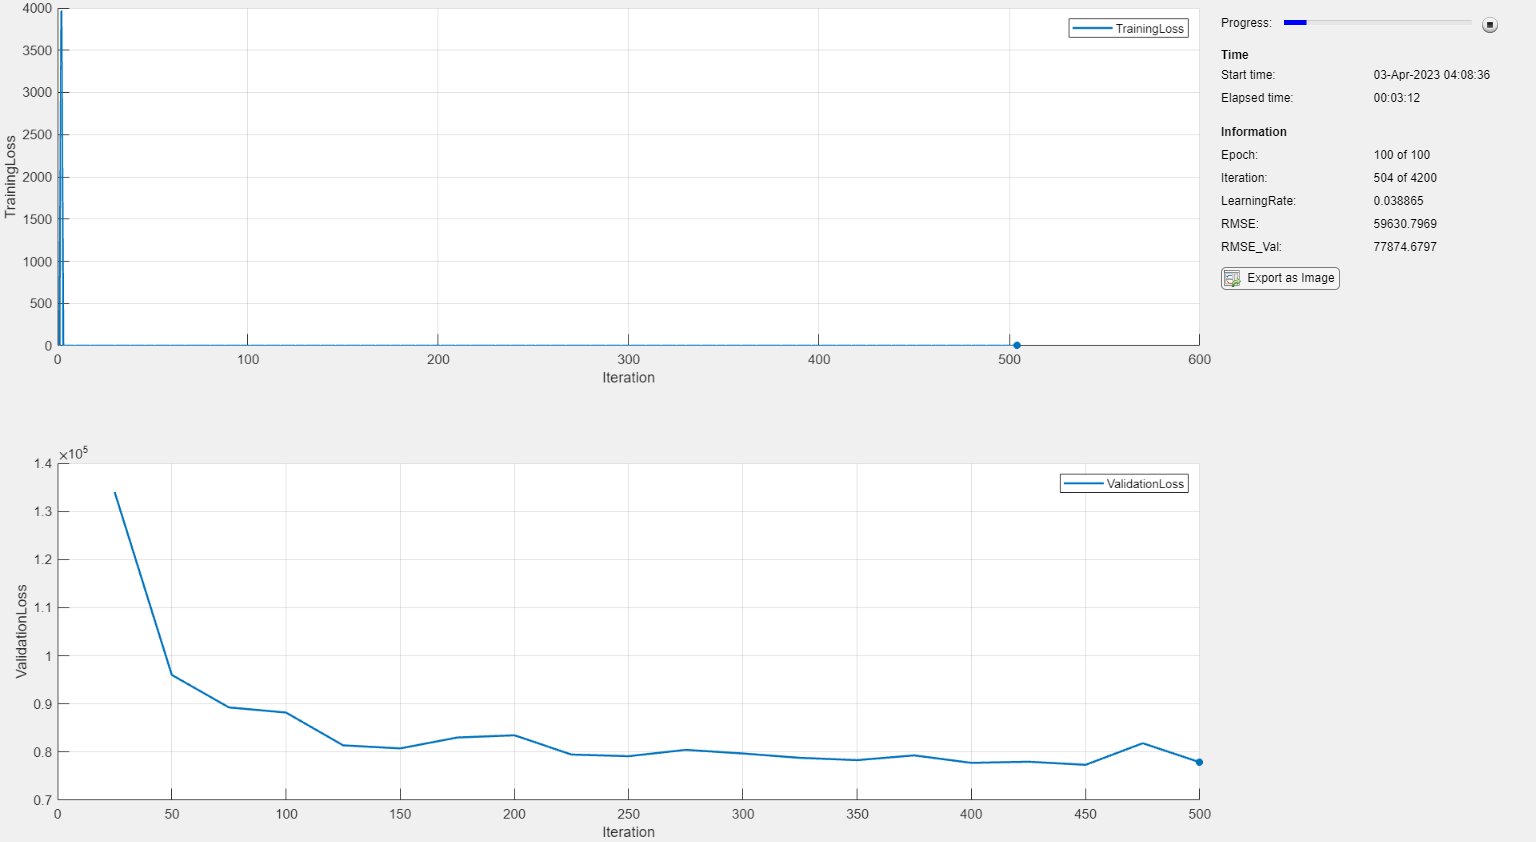

function [housing_data] = get_housing_data()
opts = delimitedTextImportOptions("NumVariables", 10);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";


% Specify column names and types
opts.VariableNames = ["longitude", "latitude", "housing_median_age", "total_rooms", "total_bedrooms", "population", "households", "median_income", "median_house_value", "ocean_proximity"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "ocean_proximity", "EmptyFieldRule", "auto");
% Import the data
housing_data = readtable("housing_ag.csv", opts);


end


function [loss,gradients,state] = modelLoss(net,X,T)

% Forward data through network.
[Y,state] = forward(net,X);

% Calculate halfed mean squarer error.

loss = mse(Y,T);

% Calculate gradients of loss with respect to learnable parameters.
gradients = dlgradient(loss,net.Learnables);

end

function [val_loss] = modelValLoss(net,x_val,y_val,S,C)
%Model's predictions
    y_val_pred = predict(net,x_val);

% Calculate halfed mean squarer error.
    val_loss = mse(y_val_pred,y_val)*2;
    val_loss = sqrt(val_loss) *S+C;
end

function [data] = get_hippo_data()

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [3, Inf];
end

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 12);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Time", "NOx", "FuelConsumption", "lambda", "ExhaustGasMassFlow", "IntakePressure", "TorqueReference", "RotSpeed", "EngineTorque", "EGRCommand", "ExhaustGasTemperature", "VarName12"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "VarName12", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "VarName12", "EmptyFieldRule", "auto");

% Import the data
data = readtable(filename, opts);
end